# MATLAB lab 2 by Patrick Spaans (11268476) & Bram Otten (10992456)

Most theory questions are answered in an accompanying PDF.

## 1 - Convolution

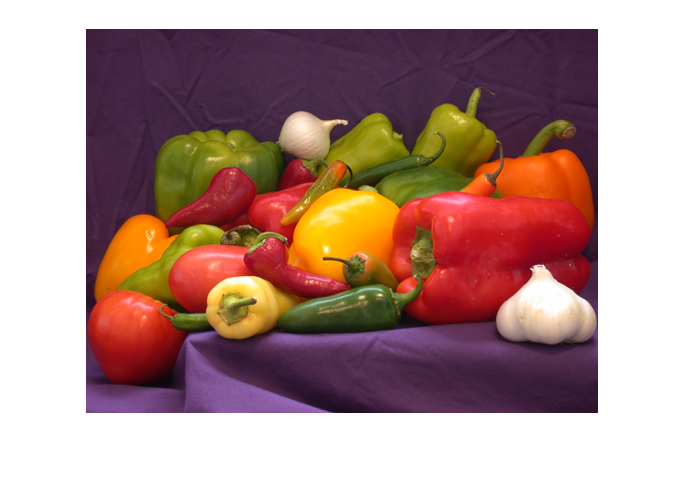

image = im2double(imread('peppers.png'));
imshow(image);

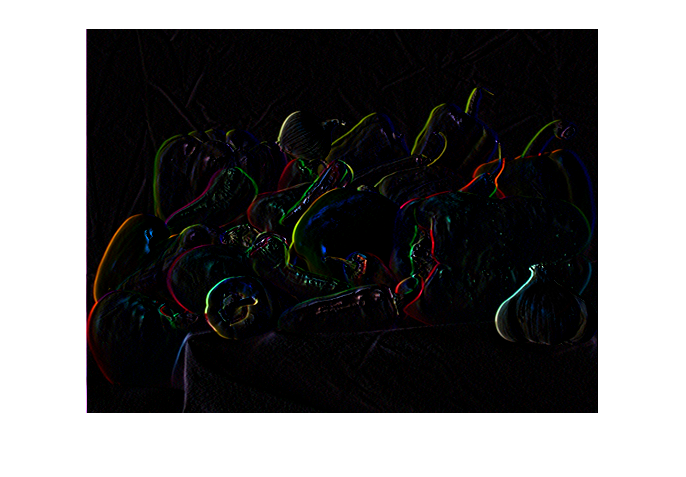

% X derivatie
horiDevConv = 1/2 * [1,0,-1];
% Default padding of imfilter is with zeroes.
horiDevImage = imfilter(image, horiDevConv, 'conv');
imshow(4 * horiDevImage);

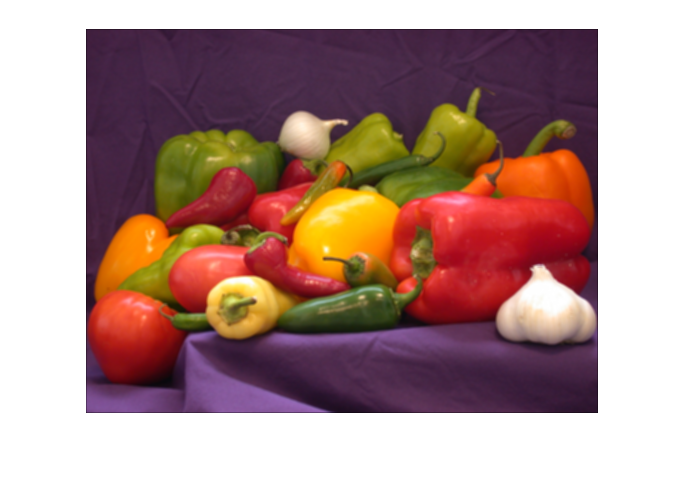

% Gaussian blur
N = 3; sigma = 3;
ind = -floor(N/2) : floor(N/2);
[X, Y] = meshgrid(ind, ind);
h = exp(-(X.^2 + Y.^2) / (2*pi*sigma^2));
gauBlurSD3 = h / sum(h(:));
blurImage = imfilter(image, gauBlurSD3, 'conv');
imshow(blurImage);

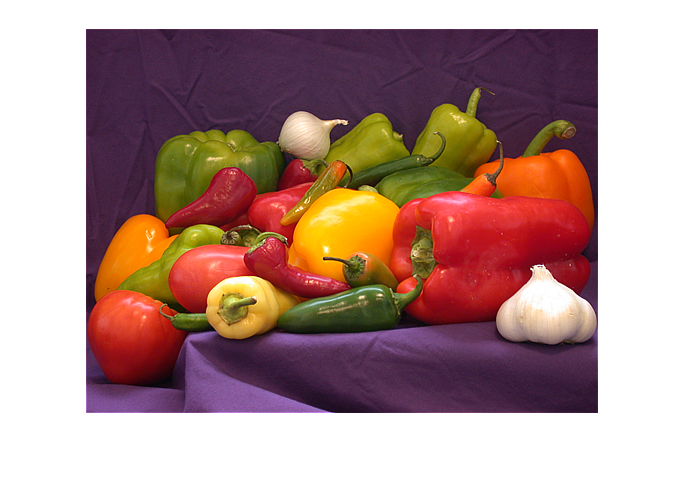

% Unsharp masking
sharpenImage = 2 * image - imfilter(image, gauBlurSD3, 'conv');
imshow(sharpenImage);

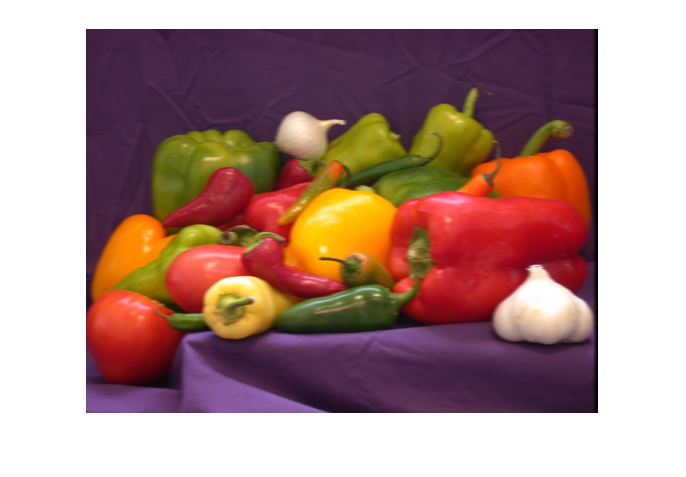

% Motion blur
optiBlurConv = 1/5 * [1,1,1,1,1,0,0,0,0,0];
optiBlurImage = imfilter(image, optiBlurConv, 'conv');
imshow(optiBlurImage);

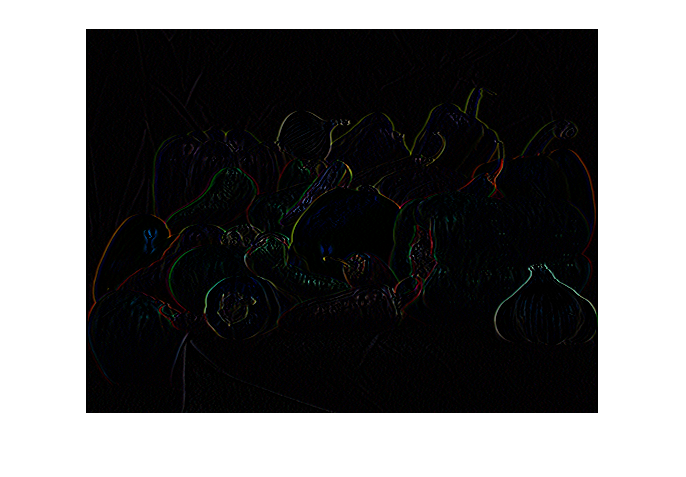

% Second x derivative
secHoriDevConv = conv2(horiDevConv, horiDevConv);
secHoriDevImage = imfilter(image, secHoriDevConv, 'conv');
imshow(4 * secHoriDevImage);

## 2 - Implementation of Gaussian Derivatives

image = im2double(imread('peppers.png')); imshow(image);

% Check out gauss.m
exGauss2 = Gauss(2)

exGauss2 =     0.1019    0.1154    0.1019
    0.1154    0.1308    0.1154
    0.1019    0.1154    0.1019


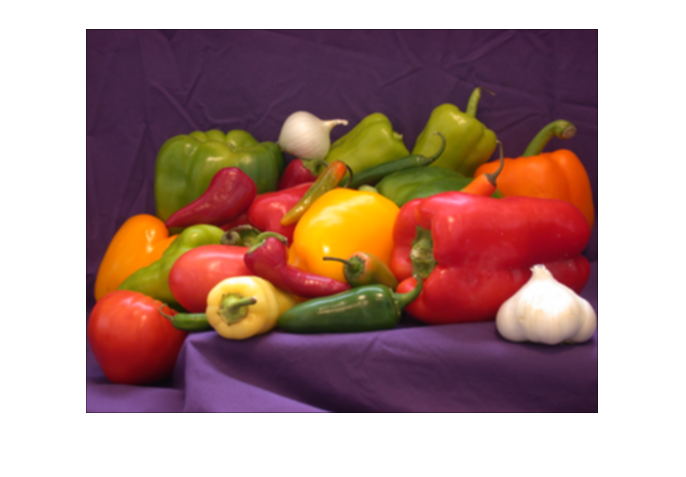

imshow(imfilter(image, exGauss2, 'conv'));

% Sum of all matrix values:
sum(sum(Gauss(3)))

ans = 1

% Expected 1 and got 1, but think the wanted result was something else,
% because normalization is not mentioned in the sample code. The fix, then, 
% is to normalize, to multiply with such a factor that the sum of the whole
% matrix becomes 1. Fixed with G = G / sum(G(:)); in Gauss.m

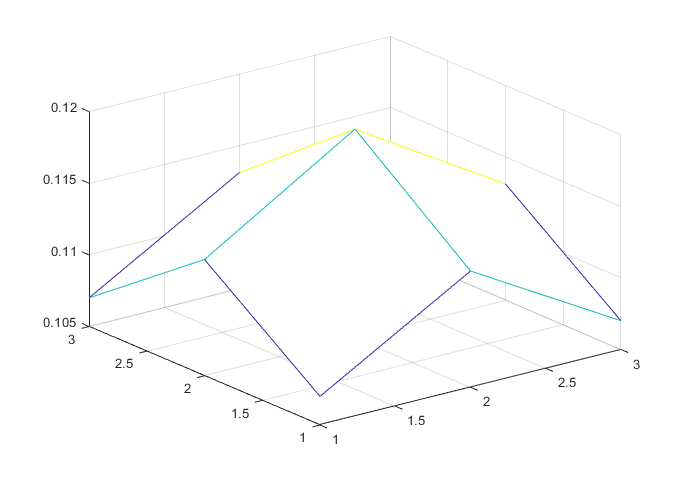

mesh(Gauss(3)); % as expected, this looks like a 2D Gaussian.

The physical unit of the scale parameter $\sigma$ is pixels, because imfilter performs a pixel-by-pixel convolution of the image and the (Gaussian) filter. $\sigma$ determines weighting of the pixels surrounding the center, the size of the filter determines how many pixels even get considered. A higher $\sigma$ means relatively higher weights for pixels surround the center, and thus more blurring.

n1 = 20; n2 = 50;
times = zeros(n1, 1);
for sigma = 1:n1
    tic;
    for i = 1:n2
        imfilter(image, Gauss(sigma), 'conv');
    end 
    times(sigma) = toc / n2;
end

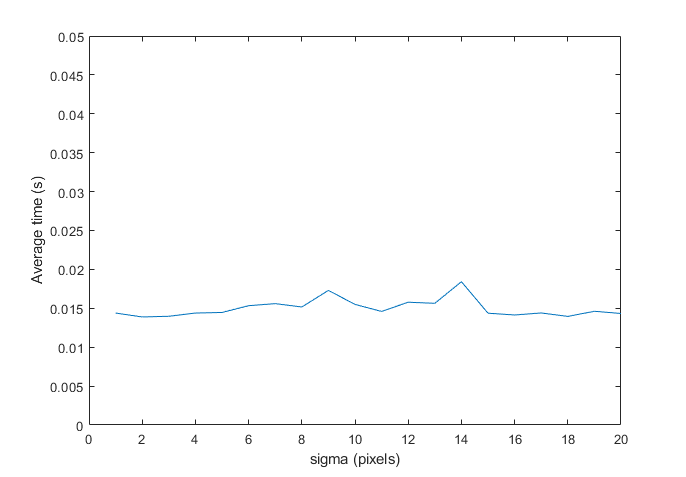

plot(times); xlabel('sigma (pixels)'); ylabel('Average time (s)'); ylim([0 .05]);

The computational complexity of Gauss seems to be $O(1)$, at least with sigma (scale) as only input argument. Of course, if M and N were to change instead of be hard-coded to something like 3 or 9, the story would probably change.

% Blurred Blur Verification

% By multiplying a Gaussian blur with a Gaussian blur, you get another 
% gaussian blur. The multiplication process works like pythagoras, with
% C = sqrt(A^2+B^2), with A and B being the Gaussians that are multiplied, 
% and C being the outcome Gaussian. Gauss(3)*Gauss(4) = Gauss(5).
image = im2double(imread('cameraman.tif'));
Doubleblur = Gauss(3)*Gauss(4);
Doubleblur = Doubleblur / sum(sum(Doubleblur)); % normalizing it so it sums to 1.
steppedBlur = imfilter(image, Doubleblur, 'conv');
directBlur = imfilter(image, Gauss(5), 'conv');
sum(sum(sum(imabsdiff(directBlur, steppedBlur)))) % near enough to 0

ans = 12.0051

% imshow(steppedBlur); imshow(directBlur);

% Check out Gauss1.m
sigma = 2; ourGauss1 = Gauss1(sigma), sum(ourGauss1) % == 1

ourGauss1 =     0.3192    0.3617    0.3192


ans = 1.0000

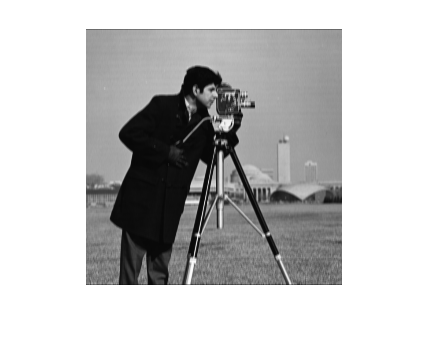

ourImage = imfilter(image, ourGauss1', 'conv');
imshow(ourImage);

n1 = 20; n2 = 50;
times = zeros(n1, 1);
for sigma = 1:n1
    tic;
    for i = 1:n2
        G = Gauss1(sigma);
        rowsOnly = imfilter(image, G', 'conv');
        imfilter(rowsOnly, G, 'conv');
    end 
    times(sigma) = toc / n2;
end

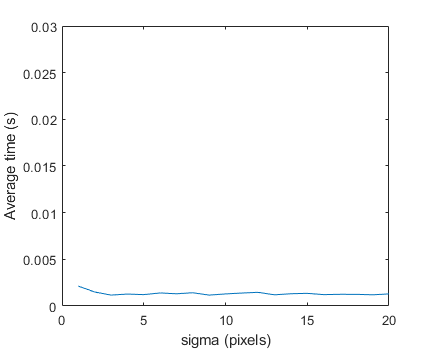

plot(times); xlabel('sigma (pixels)'); ylabel('Average time (s)'); ylim([0 .03]);

Computational complexity still seems to be $O(1)$, in other words the amount of operations does not increase along with $\sigma$. But it takes twice as long as before, probably mainly because we execute imfilter twice.

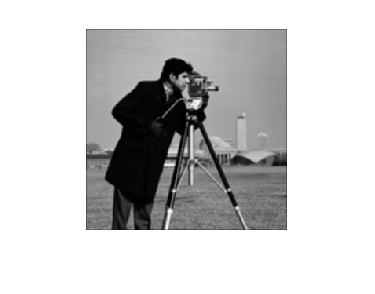

% Check out gD.m
imName = 'cameraman.tif';
image = im2double(imread(imName)); imshow(gD(image, sigma, 0, 0), []);

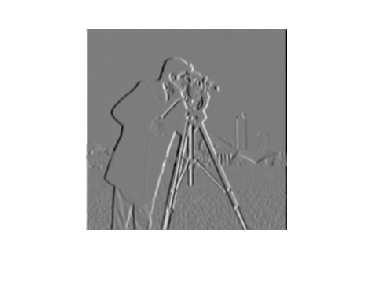

% image = rgb2gray(im2double(imread('peppers.png'))); imshow(image);
sigma = 1.2;
imageXGD = gD(image, sigma, 1, 0); imshow(imageXGD,[]); % right->left, light->dark = low values

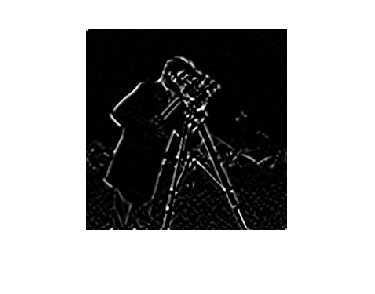

% imageXXGD = gD(image, 2, 2, 0); imshow(imageXXGD, []);
% imageYGD = gD(image, sigma, 0, 1); imshow(imageYGD); % top->bottom
% imageYYGD = gD(image, sigma, 0, 2); imshow(imageYYGD, []);
% imageXYGD = gD(image, sigma, 1, 1); imshow(imageXYGD);
imageXXYYGD = gD(image, sigma, 2, 2); imshow(13*imageXXYYGD);

## 3 - The Canny Edge Detector

Analytic derivatives of $f(x, y) = A \sin{(V x)} + B \cos{(W y)}$ :


$$f_x = A V \cos{(Vx)}$$



$$f_y = -B W \sin (W y)$$



$$f_{xx} = - A V^2 \sin (V x)$$



$$f_{yy} = - B W^2 \sin (W y)$$



$$f_{xy} = A V \cos (V x) - B W \sin (W y)$$


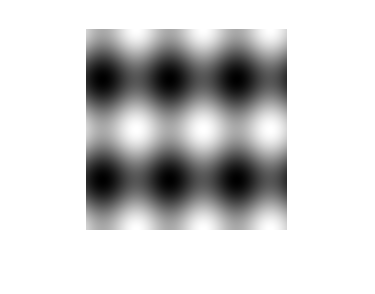

x = -100:100; y = x;
[X, Y] = meshgrid(x, y);
A = 1; B = 2; V = 6 * pi / 201; W = 4 * pi / 201;
F = A * sin(V*X) + B * cos(W*Y);
imshow(F, [], 'xData', x, 'yData', y);

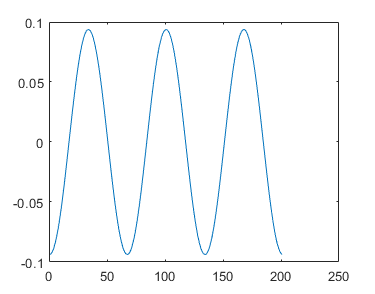

Fx = A * V * cos(V * x);
Fy = - B * W * sin(W * y);
plot(Fx);

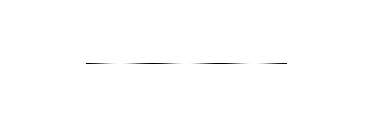

imshow(Fx, [], 'x', x); % super small range, so showing an image is useless.

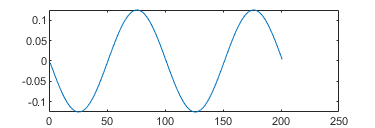

plot(Fy);

Fy =    -0.0039   -0.0117   -0.0195   -0.0271   -0.0347   -0.0422   -0.0494   -0.0565   -0.0634   -0.0700   -0.0763   -0.0824   -0.0881   -0.0934   -0.0985   -0.1031   -0.1073   -0.1111   -0.1145   -0.1174   -0.1198   -0.1218   -0.1234   -0.1244   -0.1249   -0.1250   -0.1246   -0.1237   -0.1223   -0.1204   -0.1180   -0.1152   -0.1120   -0.1083   -0.1042   -0.0996   -0.0947   -0.0894   -0.0838   -0.0779   -0.0716   -0.0650   -0.0582   -0.0512   -0.0440   -0.0366   -0.0290   -0.0214   -0.0137   -0.0059


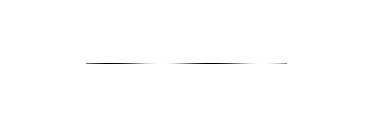

Fy, imshow(Fy, [], 'x', y);

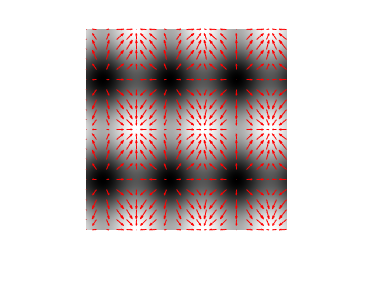

xx = -100:10:100;
yy = -100:10:100;
[XX , YY] = meshgrid (xx, yy);
Fx = A * V * cos(V * XX);
Fy = - B * W * sin(W * YY);
imshow (F , [] , 'xData' , x, 'yData' , y);
hold on ;
quiver(xx, yy, Fx, Fy, 'r');
hold off;

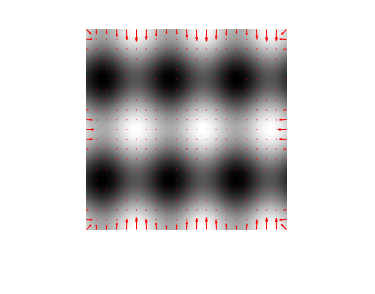

% gD and imfilter
Gx = gD(F, 1, 1, 0);
Gy = gD(F, 1, 0, 1);

Gx = Gx(1:10:end, 1:10:end);
Gy = Gy(1:10:end, 1:10:end);

imshow (F , [] , 'xData' , x, 'yData' , y);
hold on ;
quiver(xx, yy, Gx, Gy, 'r'); % that scale suggestion doesn't work.
hold off;

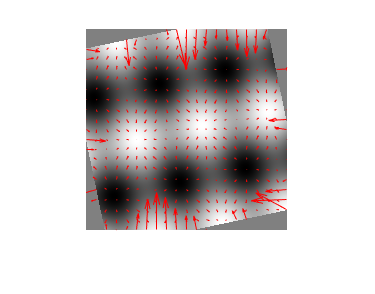

% Rotate F by a small angle and plot like before again.
F2 = rotatedImage(F, -pi/15, 'linear');
Gx = gD(F2, 1, 1, 0);
Gy = gD(F2, 1, 0, 1);

Gx = Gx(1:10:end, 1:10:end);
Gy = Gy(1:10:end, 1:10:end);

imshow (F2 , [] , 'xData' , x, 'yData' , y);
hold on ;
quiver(xx, yy, Gx, Gy, 3, 'r');

hold off;

The gradient vectors have rotated along with the image. Nearly all vectors still hold up and move from dark to lighter. However, it doesn't look as good as before, since the mesh no longer follows the borders perfectly, and those had the most distinctive vectors. Some vectors move into the border, since the border is gray, and gray is lighter than black.

Analytic derivation of derivatives in local gradient direction:

$w$ is by definition the direction of the gradient. So its derivative is just some constant factor, the function values go up in that direction. Normalizing by the length of the vector that gives us this direction, $(f_x \ f_y)^T$, gives us:


$$f_w  = \sqrt{f_x^2 + f_y^2}$$


Everything in this new $(v,w)$ coordinate system is just the $(x,y)$ stuff rotated. And so it is with the Hessian $H_f$ containing $f_{xx}$ and such. Applying $R \ H_f \ R^T$ and some power of Leo, this gives a new Hessian containing:


$$f_{ww} = \frac{f_x^2f_{xx} + 2f_xf_yf_{xy} + f_y^2f_{yy}}{f_x^2 + f_y^2}$$


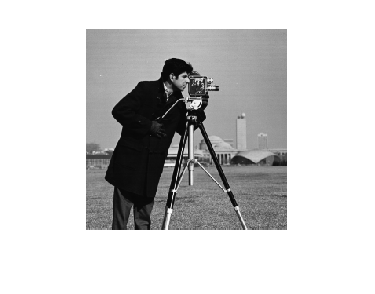

% The Canny edge detector - most work done in canny.m
imName = 'cameraman.tif';
image = im2double(imread(imName)); imshow(image);

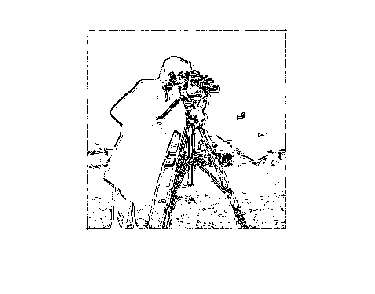

sigma = 1; threshold = .07;
e = canny(image, sigma, threshold);
imshow(imcomplement(e));

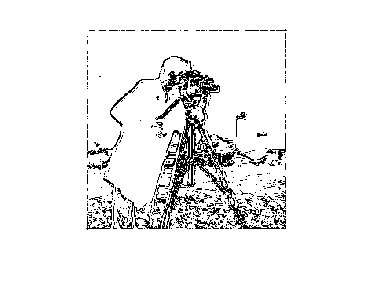

sigma = 1; threshold = .042;
e = canny(image, sigma, threshold);
imshow(imcomplement(e));

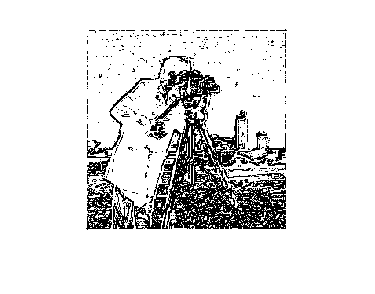

sigma = 1; threshold = .012;
e = canny(image, sigma, threshold);
imshow(imcomplement(e));

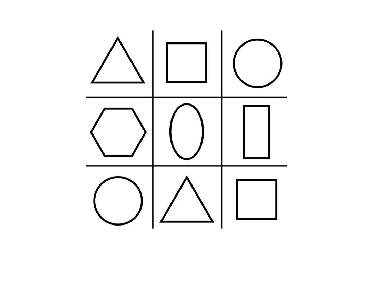

% Corner detection
sigma = 1.5;
c = edgeDetector9000(image, sigma);
image = rgb2gray(im2double(imread('mokerCool.jpg')));
imshow(image);

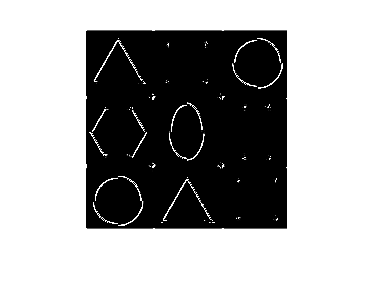

c = edgeDetector9000(image, sigma);
imshow(c); % square becomes 4 dots, not sure about the rest.